# ECG Classification using tranfer learning GoogLeNet

% parentDir = '\\uofa\users$\users0\a1798520\MATLAB\CNNs\myFolder';
% dataDir = 'data';
% helperCreateECGDirectories(ECGData,parentDir,dataDir)

%Generating scalograms
%helperCreateRGBfromTF(ECGData,parentDir,dataDir)

%store images
allImages = imageDatastore(fullfile(parentDir,dataDir),...
     'IncludeSubfolders',true,...
    'LabelSource','foldernames');

% %training vs testing
rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 3200


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 800


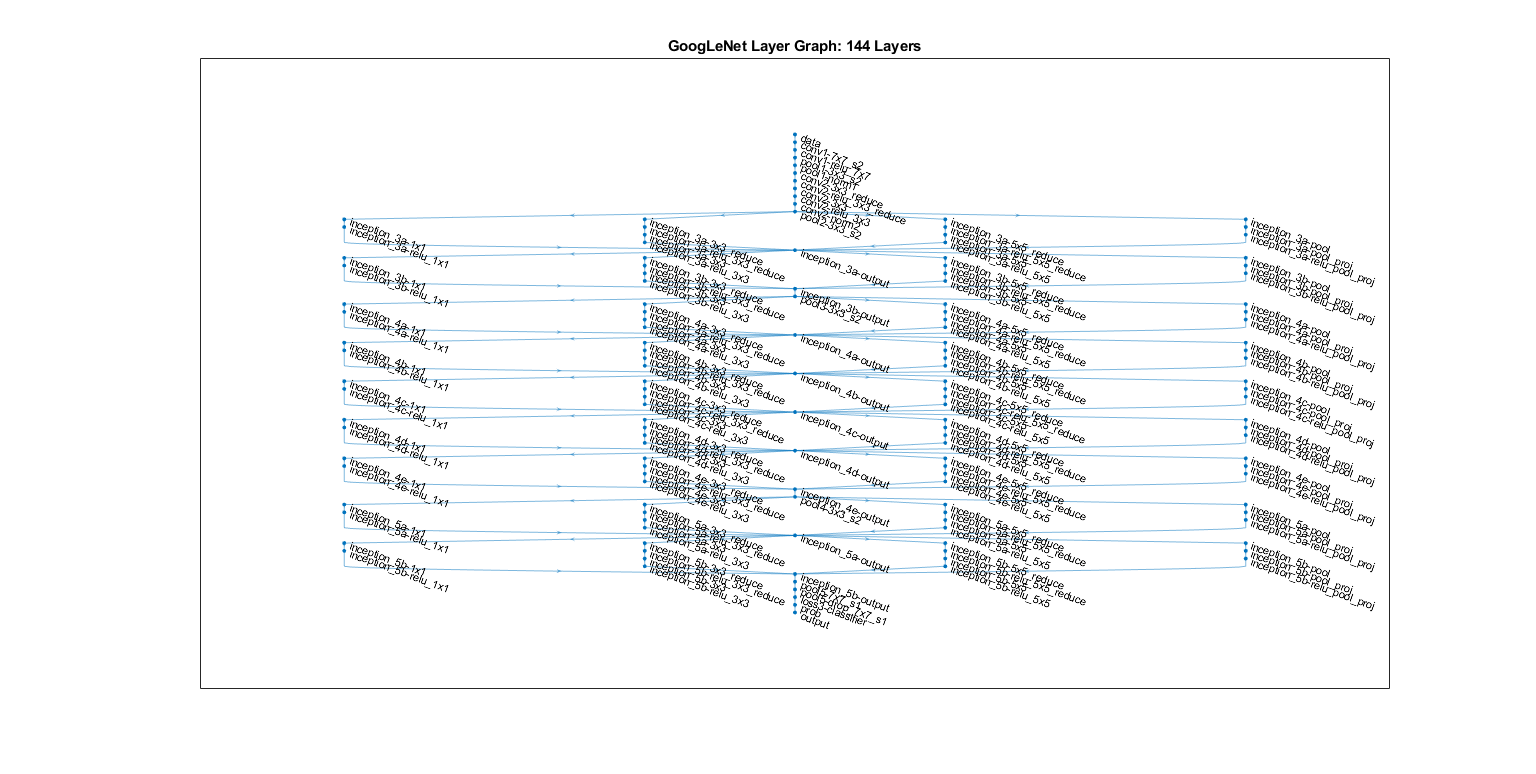

%  net = googlenet;
 lgraph = layerGraph(net);
 numberOfLayers = numel(lgraph.Layers);
 figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
 plot(lgraph)
 title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

 
net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


% Modify GoogLeNet Network Parameters
newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

%Set Training Options and Train GoogLeNet
options = trainingOptions('sgdm',...
    'MiniBatchSize',10,...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress');
rng default

%train
% trainedGN = trainNetwork(imgsTrain,lgraph,options);

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:19 |       60.00% |       51.13% |       1.0369 |       1.0852 |      1.0000e-04 |


|       1 |          10 |       00:00:31 |       50.00% |       58.00% |       1.3002 |       0.7621 |      1.0000e-04 |


|       1 |          20 |       00:00:37 |       70.00% |       65.13% |       0.6679 |       0.6844 |      1.0000e-04 |


|       1 |          30 |       00:00:43 |       90.00% |       76.25% |       0.2465 |       0.4834 |      1.0000e-04 |


|       1 |          40 |       00:00:50 |       90.00% |       82.88% |       0.2721 |       0.3826 |      1.0000e-04 |


|       1 |          50 |       00:00:56 |       60.00% |       84.50% |       0.5186 |       0.3287 |      1.0000e-04 |


|       1 |          60 |       00:01:02 |       80.00% |       86.88% |       0.3921 |       0.3038 |      1.0000e-04 |


|       1 |          70 |       00:01:09 |      100.00% |       84.00% |       0.1802 |       0.3473 |      1.0000e-04 |


|       1 |          80 |       00:01:15 |       80.00% |       86.63% |       0.4585 |       0.2994 |      1.0000e-04 |


|       1 |          90 |       00:01:21 |       80.00% |       85.75% |       0.6200 |       0.3068 |      1.0000e-04 |


|       1 |         100 |       00:01:27 |       90.00% |       84.88% |       0.4582 |       0.3304 |      1.0000e-04 |


|       1 |         110 |       00:01:34 |       90.00% |       88.25% |       0.5658 |       0.2730 |      1.0000e-04 |


|       1 |         120 |       00:01:40 |       90.00% |       88.63% |       0.4294 |       0.2643 |      1.0000e-04 |


|       1 |         130 |       00:01:47 |       80.00% |       88.38% |       0.2663 |       0.2593 |      1.0000e-04 |


|       1 |         140 |       00:01:53 |      100.00% |       85.13% |       0.0298 |       0.3362 |      1.0000e-04 |


|       1 |         150 |       00:01:59 |       60.00% |       88.75% |       0.4262 |       0.2603 |      1.0000e-04 |


|       1 |         160 |       00:02:05 |       80.00% |       83.63% |       0.2092 |       0.3726 |      1.0000e-04 |


|       1 |         170 |       00:02:12 |       90.00% |       88.75% |       0.3909 |       0.2838 |      1.0000e-04 |


|       1 |         180 |       00:02:18 |       70.00% |       88.50% |       0.5329 |       0.2430 |      1.0000e-04 |


|       1 |         190 |       00:02:24 |       90.00% |       88.88% |       0.1696 |       0.2632 |      1.0000e-04 |


|       1 |         200 |       00:02:31 |       80.00% |       89.50% |       0.1841 |       0.2339 |      1.0000e-04 |


|       1 |         210 |       00:02:37 |      100.00% |       89.63% |       0.1861 |       0.2641 |      1.0000e-04 |


|       1 |         220 |       00:02:44 |       70.00% |       90.63% |       0.3763 |       0.2327 |      1.0000e-04 |


|       1 |         230 |       00:02:50 |       80.00% |       85.00% |       0.6713 |       0.3565 |      1.0000e-04 |


|       1 |         240 |       00:02:56 |       60.00% |       90.38% |       0.6341 |       0.2453 |      1.0000e-04 |


|       1 |         250 |       00:03:02 |      100.00% |       91.38% |       0.0805 |       0.2128 |      1.0000e-04 |


|       1 |         260 |       00:03:09 |       90.00% |       92.00% |       0.2010 |       0.2095 |      1.0000e-04 |


|       1 |         270 |       00:03:15 |      100.00% |       92.13% |       0.1284 |       0.2129 |      1.0000e-04 |


|       1 |         280 |       00:03:21 |      100.00% |       91.13% |       0.0714 |       0.2225 |      1.0000e-04 |


|       1 |         290 |       00:03:28 |       70.00% |       92.00% |       0.7558 |       0.2058 |      1.0000e-04 |


|       1 |         300 |       00:03:34 |       90.00% |       90.88% |       0.2665 |       0.2293 |      1.0000e-04 |


|       1 |         310 |       00:03:41 |      100.00% |       92.50% |       0.1724 |       0.2031 |      1.0000e-04 |


|       1 |         320 |       00:03:47 |       90.00% |       90.75% |       0.1374 |       0.2285 |      1.0000e-04 |


|       2 |         330 |       00:03:54 |      100.00% |       92.50% |       0.0616 |       0.2008 |      1.0000e-04 |


|       2 |         340 |       00:04:00 |       70.00% |       92.25% |       0.4069 |       0.2079 |      1.0000e-04 |


|       2 |         350 |       00:04:06 |      100.00% |       91.50% |       0.1286 |       0.2346 |      1.0000e-04 |


|       2 |         360 |       00:04:13 |       90.00% |       91.63% |       0.4036 |       0.2006 |      1.0000e-04 |


|       2 |         370 |       00:04:19 |       90.00% |       91.88% |       0.3166 |       0.1983 |      1.0000e-04 |


|       2 |         380 |       00:04:26 |       80.00% |       92.38% |       0.3543 |       0.2046 |      1.0000e-04 |


|       2 |         390 |       00:04:32 |       90.00% |       92.75% |       0.2887 |       0.1878 |      1.0000e-04 |


|       2 |         400 |       00:04:38 |       90.00% |       92.13% |       0.1728 |       0.2006 |      1.0000e-04 |


|       2 |         410 |       00:04:45 |       90.00% |       93.38% |       0.3600 |       0.1812 |      1.0000e-04 |


|       2 |         420 |       00:04:51 |      100.00% |       93.00% |       0.1073 |       0.1799 |      1.0000e-04 |


|       2 |         430 |       00:04:58 |       90.00% |       92.25% |       0.1537 |       0.1896 |      1.0000e-04 |


|       2 |         440 |       00:05:04 |       90.00% |       93.38% |       0.2652 |       0.1746 |      1.0000e-04 |


|       2 |         450 |       00:05:11 |       90.00% |       93.25% |       0.2529 |       0.1726 |      1.0000e-04 |


|       2 |         460 |       00:05:17 |      100.00% |       91.75% |       0.0466 |       0.2063 |      1.0000e-04 |


|       2 |         470 |       00:05:23 |       90.00% |       94.00% |       0.2040 |       0.1767 |      1.0000e-04 |


|       2 |         480 |       00:05:30 |      100.00% |       88.00% |       0.0895 |       0.2848 |      1.0000e-04 |


|       2 |         490 |       00:05:36 |       90.00% |       93.13% |       0.2805 |       0.1758 |      1.0000e-04 |


|       2 |         500 |       00:05:43 |       90.00% |       93.63% |       0.3755 |       0.1705 |      1.0000e-04 |


|       2 |         510 |       00:05:49 |       90.00% |       93.38% |       0.1442 |       0.1704 |      1.0000e-04 |


|       2 |         520 |       00:05:55 |       90.00% |       94.63% |       0.1490 |       0.1683 |      1.0000e-04 |


|       2 |         530 |       00:06:02 |      100.00% |       92.88% |       0.0730 |       0.1756 |      1.0000e-04 |


|       2 |         540 |       00:06:08 |       80.00% |       93.13% |       0.2236 |       0.1723 |      1.0000e-04 |


|       2 |         550 |       00:06:14 |       90.00% |       91.13% |       0.0917 |       0.2219 |      1.0000e-04 |


|       2 |         560 |       00:06:21 |       80.00% |       94.00% |       0.6253 |       0.1605 |      1.0000e-04 |


|       2 |         570 |       00:06:27 |       90.00% |       93.00% |       0.0949 |       0.1776 |      1.0000e-04 |


|       2 |         580 |       00:06:33 |      100.00% |       92.75% |       0.0709 |       0.1658 |      1.0000e-04 |


|       2 |         590 |       00:06:40 |      100.00% |       94.88% |       0.1216 |       0.1502 |      1.0000e-04 |


|       2 |         600 |       00:06:46 |      100.00% |       91.88% |       0.0470 |       0.1857 |      1.0000e-04 |


|       2 |         610 |       00:06:53 |       80.00% |       94.88% |       0.4461 |       0.1511 |      1.0000e-04 |


|       2 |         620 |       00:06:59 |       80.00% |       95.75% |       0.2337 |       0.1495 |      1.0000e-04 |


|       2 |         630 |       00:07:06 |       90.00% |       95.25% |       0.1833 |       0.1477 |      1.0000e-04 |


|       2 |         640 |       00:07:12 |      100.00% |       92.38% |       0.1574 |       0.1737 |      1.0000e-04 |


|       3 |         650 |       00:07:18 |      100.00% |       94.50% |       0.0119 |       0.1491 |      1.0000e-04 |


|       3 |         660 |       00:07:25 |       80.00% |       95.00% |       0.4403 |       0.1482 |      1.0000e-04 |


|       3 |         670 |       00:07:31 |      100.00% |       92.50% |       0.0549 |       0.1846 |      1.0000e-04 |


|       3 |         680 |       00:07:38 |       90.00% |       94.25% |       0.3654 |       0.1476 |      1.0000e-04 |


|       3 |         690 |       00:07:44 |      100.00% |       94.00% |       0.2564 |       0.1554 |      1.0000e-04 |


|       3 |         700 |       00:07:50 |       80.00% |       94.88% |       0.3568 |       0.1409 |      1.0000e-04 |


|       3 |         710 |       00:07:57 |       90.00% |       94.75% |       0.3655 |       0.1387 |      1.0000e-04 |


|       3 |         720 |       00:08:03 |       90.00% |       92.25% |       0.4507 |       0.1762 |      1.0000e-04 |


|       3 |         730 |       00:08:10 |      100.00% |       95.13% |       0.0750 |       0.1396 |      1.0000e-04 |


|       3 |         740 |       00:08:16 |      100.00% |       95.75% |       0.0246 |       0.1300 |      1.0000e-04 |


|       3 |         750 |       00:08:22 |       90.00% |       95.00% |       0.1159 |       0.1423 |      1.0000e-04 |


|       3 |         760 |       00:08:29 |       90.00% |       95.13% |       0.2210 |       0.1369 |      1.0000e-04 |


|       3 |         770 |       00:08:35 |       80.00% |       95.25% |       0.2148 |       0.1303 |      1.0000e-04 |


|       3 |         780 |       00:08:42 |      100.00% |       96.00% |       0.0371 |       0.1308 |      1.0000e-04 |


|       3 |         790 |       00:08:48 |      100.00% |       94.88% |       0.0684 |       0.1442 |      1.0000e-04 |


|       3 |         800 |       00:08:54 |      100.00% |       92.88% |       0.0725 |       0.1630 |      1.0000e-04 |


|       3 |         810 |       00:09:01 |      100.00% |       96.13% |       0.1624 |       0.1210 |      1.0000e-04 |


|       3 |         820 |       00:09:08 |       90.00% |       95.75% |       0.1428 |       0.1252 |      1.0000e-04 |


|       3 |         830 |       00:09:14 |      100.00% |       96.13% |       0.0396 |       0.1202 |      1.0000e-04 |


|       3 |         840 |       00:09:20 |      100.00% |       95.88% |       0.0565 |       0.1195 |      1.0000e-04 |


|       3 |         850 |       00:09:27 |      100.00% |       96.00% |       0.0174 |       0.1293 |      1.0000e-04 |


|       3 |         860 |       00:09:33 |      100.00% |       95.13% |       0.0497 |       0.1378 |      1.0000e-04 |


|       3 |         870 |       00:09:40 |      100.00% |       92.25% |       0.0210 |       0.1830 |      1.0000e-04 |


|       3 |         880 |       00:09:46 |       80.00% |       94.88% |       0.3535 |       0.1267 |      1.0000e-04 |


|       3 |         890 |       00:09:52 |      100.00% |       95.13% |       0.0203 |       0.1331 |      1.0000e-04 |


|       3 |         900 |       00:09:59 |      100.00% |       94.50% |       0.0915 |       0.1342 |      1.0000e-04 |


|       3 |         910 |       00:10:05 |      100.00% |       96.38% |       0.0357 |       0.1144 |      1.0000e-04 |


|       3 |         920 |       00:10:11 |      100.00% |       94.00% |       0.0099 |       0.1399 |      1.0000e-04 |


|       3 |         930 |       00:10:18 |       80.00% |       96.25% |       0.2498 |       0.1134 |      1.0000e-04 |


|       3 |         940 |       00:10:24 |       90.00% |       95.63% |       0.1408 |       0.1191 |      1.0000e-04 |


|       3 |         950 |       00:10:31 |      100.00% |       95.88% |       0.0236 |       0.1222 |      1.0000e-04 |


|       3 |         960 |       00:10:37 |       90.00% |       94.13% |       0.1367 |       0.1416 |      1.0000e-04 |


|       4 |         970 |       00:10:44 |      100.00% |       96.88% |       0.0577 |       0.1188 |      1.0000e-04 |


|       4 |         980 |       00:10:50 |       80.00% |       96.88% |       0.3592 |       0.1221 |      1.0000e-04 |


|       4 |         990 |       00:10:57 |      100.00% |       92.50% |       0.0229 |       0.1806 |      1.0000e-04 |


|       4 |        1000 |       00:11:03 |       90.00% |       96.38% |       0.0974 |       0.1160 |      1.0000e-04 |


|       4 |        1010 |       00:11:10 |      100.00% |       96.00% |       0.1729 |       0.1147 |      1.0000e-04 |


|       4 |        1020 |       00:11:16 |       90.00% |       97.00% |       0.2460 |       0.1106 |      1.0000e-04 |


|       4 |        1030 |       00:11:22 |       90.00% |       97.25% |       0.1559 |       0.1042 |      1.0000e-04 |


|       4 |        1040 |       00:11:29 |      100.00% |       95.63% |       0.0493 |       0.1204 |      1.0000e-04 |


|       4 |        1050 |       00:11:35 |      100.00% |       96.75% |       0.1053 |       0.1058 |      1.0000e-04 |


|       4 |        1060 |       00:11:41 |      100.00% |       96.25% |       0.0326 |       0.1027 |      1.0000e-04 |


|       4 |        1070 |       00:11:48 |       90.00% |       96.25% |       0.0891 |       0.1062 |      1.0000e-04 |


|       4 |        1080 |       00:11:54 |       90.00% |       96.25% |       0.2614 |       0.1015 |      1.0000e-04 |


|       4 |        1090 |       00:12:01 |       90.00% |       96.13% |       0.1185 |       0.1037 |      1.0000e-04 |


|       4 |        1100 |       00:12:07 |      100.00% |       95.75% |       0.0074 |       0.1221 |      1.0000e-04 |


|       4 |        1110 |       00:12:13 |      100.00% |       96.13% |       0.0966 |       0.1095 |      1.0000e-04 |


|       4 |        1120 |       00:12:19 |      100.00% |       91.00% |       0.0993 |       0.1943 |      1.0000e-04 |


|       4 |        1130 |       00:12:26 |       90.00% |       97.00% |       0.1565 |       0.0985 |      1.0000e-04 |


|       4 |        1140 |       00:12:32 |      100.00% |       96.75% |       0.1364 |       0.0961 |      1.0000e-04 |


|       4 |        1150 |       00:12:39 |      100.00% |       97.00% |       0.0530 |       0.0974 |      1.0000e-04 |


|       4 |        1160 |       00:12:45 |      100.00% |       96.88% |       0.0949 |       0.0965 |      1.0000e-04 |


|       4 |        1170 |       00:12:52 |      100.00% |       97.13% |       0.0434 |       0.0935 |      1.0000e-04 |


|       4 |        1180 |       00:12:58 |      100.00% |       95.75% |       0.0069 |       0.1106 |      1.0000e-04 |


|       4 |        1190 |       00:13:04 |      100.00% |       95.75% |       0.0088 |       0.1085 |      1.0000e-04 |


|       4 |        1200 |       00:13:11 |       90.00% |       96.38% |       0.3035 |       0.0959 |      1.0000e-04 |


|       4 |        1210 |       00:13:18 |      100.00% |       95.63% |       0.0130 |       0.1071 |      1.0000e-04 |


|       4 |        1220 |       00:13:24 |       90.00% |       96.38% |       0.1036 |       0.0990 |      1.0000e-04 |


|       4 |        1230 |       00:13:31 |      100.00% |       97.00% |       0.0263 |       0.0932 |      1.0000e-04 |


|       4 |        1240 |       00:13:37 |      100.00% |       95.38% |       0.0236 |       0.1111 |      1.0000e-04 |


|       4 |        1250 |       00:13:44 |       80.00% |       96.25% |       0.2413 |       0.0978 |      1.0000e-04 |


|       4 |        1260 |       00:13:50 |      100.00% |       96.88% |       0.0566 |       0.1004 |      1.0000e-04 |


|       4 |        1270 |       00:13:56 |      100.00% |       97.25% |       0.0457 |       0.0923 |      1.0000e-04 |


|       4 |        1280 |       00:14:03 |      100.00% |       95.13% |       0.0125 |       0.1211 |      1.0000e-04 |


|       5 |        1290 |       00:14:09 |      100.00% |       97.38% |       0.0106 |       0.0961 |      1.0000e-04 |


|       5 |        1300 |       00:14:15 |       90.00% |       96.25% |       0.3741 |       0.1121 |      1.0000e-04 |


|       5 |        1310 |       00:14:29 |      100.00% |       94.63% |       0.0083 |       0.1414 |      1.0000e-04 |


|       5 |        1320 |       00:14:35 |      100.00% |       96.75% |       0.0657 |       0.0963 |      1.0000e-04 |


|       5 |        1330 |       00:14:42 |      100.00% |       96.00% |       0.0564 |       0.1087 |      1.0000e-04 |


|       5 |        1340 |       00:14:48 |      100.00% |       97.50% |       0.0218 |       0.0916 |      1.0000e-04 |


|       5 |        1350 |       00:14:54 |       90.00% |       96.63% |       0.2306 |       0.0953 |      1.0000e-04 |


|       5 |        1360 |       00:15:00 |      100.00% |       97.00% |       0.0242 |       0.0911 |      1.0000e-04 |


|       5 |        1370 |       00:15:07 |      100.00% |       97.13% |       0.0642 |       0.0858 |      1.0000e-04 |


|       5 |        1380 |       00:15:13 |      100.00% |       97.13% |       0.0078 |       0.0827 |      1.0000e-04 |


|       5 |        1390 |       00:15:20 |      100.00% |       96.13% |       0.0352 |       0.1096 |      1.0000e-04 |


|       5 |        1400 |       00:15:27 |       90.00% |       96.50% |       0.1402 |       0.0990 |      1.0000e-04 |


|       5 |        1410 |       00:15:33 |      100.00% |       96.88% |       0.0355 |       0.0936 |      1.0000e-04 |


|       5 |        1420 |       00:15:40 |      100.00% |       97.50% |       0.0078 |       0.0841 |      1.0000e-04 |


|       5 |        1430 |       00:15:46 |      100.00% |       97.13% |       0.0458 |       0.0910 |      1.0000e-04 |


|       5 |        1440 |       00:15:53 |      100.00% |       96.00% |       0.0162 |       0.1093 |      1.0000e-04 |


|       5 |        1450 |       00:16:00 |       90.00% |       97.88% |       0.1134 |       0.0778 |      1.0000e-04 |


|       5 |        1460 |       00:16:07 |      100.00% |       97.38% |       0.0917 |       0.0786 |      1.0000e-04 |


|       5 |        1470 |       00:16:14 |       90.00% |       97.63% |       0.1152 |       0.0818 |      1.0000e-04 |


|       5 |        1480 |       00:16:20 |      100.00% |       97.38% |       0.0456 |       0.0768 |      1.0000e-04 |


|       5 |        1490 |       00:16:27 |      100.00% |       97.13% |       0.0136 |       0.0774 |      1.0000e-04 |


|       5 |        1500 |       00:16:34 |      100.00% |       95.88% |       0.0540 |       0.1078 |      1.0000e-04 |


|       5 |        1510 |       00:16:41 |      100.00% |       95.38% |       0.0200 |       0.1219 |      1.0000e-04 |


|       5 |        1520 |       00:16:47 |       80.00% |       97.13% |       0.2427 |       0.0769 |      1.0000e-04 |


|       5 |        1530 |       00:16:55 |      100.00% |       97.50% |       0.0133 |       0.0769 |      1.0000e-04 |


|       5 |        1540 |       00:17:01 |      100.00% |       96.88% |       0.0517 |       0.0863 |      1.0000e-04 |


|       5 |        1550 |       00:17:09 |      100.00% |       97.63% |       0.0492 |       0.0760 |      1.0000e-04 |


|       5 |        1560 |       00:17:15 |      100.00% |       96.50% |       0.0023 |       0.0967 |      1.0000e-04 |


|       5 |        1570 |       00:17:22 |      100.00% |       97.00% |       0.0778 |       0.0789 |      1.0000e-04 |


|       5 |        1580 |       00:17:29 |      100.00% |       97.50% |       0.0158 |       0.0805 |      1.0000e-04 |


|       5 |        1590 |       00:17:35 |      100.00% |       97.25% |       0.0154 |       0.0778 |      1.0000e-04 |


|       5 |        1600 |       00:17:41 |      100.00% |       95.38% |       0.0092 |       0.1141 |      1.0000e-04 |


|       6 |        1610 |       00:17:48 |      100.00% |       97.38% |       0.0045 |       0.0821 |      1.0000e-04 |


|       6 |        1620 |       00:17:54 |       90.00% |       97.13% |       0.4129 |       0.0947 |      1.0000e-04 |


|       6 |        1630 |       00:18:00 |      100.00% |       95.63% |       0.0046 |       0.1096 |      1.0000e-04 |


|       6 |        1640 |       00:18:07 |      100.00% |       96.63% |       0.0590 |       0.0905 |      1.0000e-04 |


|       6 |        1650 |       00:18:13 |      100.00% |       97.00% |       0.0655 |       0.0860 |      1.0000e-04 |


|       6 |        1660 |       00:18:19 |      100.00% |       97.88% |       0.0692 |       0.0728 |      1.0000e-04 |


|       6 |        1670 |       00:18:26 |      100.00% |       97.88% |       0.0565 |       0.0753 |      1.0000e-04 |


|       6 |        1680 |       00:18:32 |      100.00% |       96.75% |       0.0369 |       0.0884 |      1.0000e-04 |


|       6 |        1690 |       00:18:38 |      100.00% |       97.63% |       0.0224 |       0.0728 |      1.0000e-04 |


|       6 |        1700 |       00:18:45 |      100.00% |       98.00% |       0.0052 |       0.0689 |      1.0000e-04 |


|       6 |        1710 |       00:18:51 |      100.00% |       97.38% |       0.0499 |       0.0762 |      1.0000e-04 |


|       6 |        1720 |       00:18:57 |      100.00% |       97.63% |       0.0255 |       0.0696 |      1.0000e-04 |


|       6 |        1730 |       00:19:04 |      100.00% |       97.50% |       0.0608 |       0.0727 |      1.0000e-04 |


|       6 |        1740 |       00:19:10 |      100.00% |       97.63% |       0.0224 |       0.0717 |      1.0000e-04 |


|       6 |        1750 |       00:19:16 |      100.00% |       97.63% |       0.0695 |       0.0703 |      1.0000e-04 |


|       6 |        1760 |       00:19:22 |      100.00% |       96.75% |       0.0134 |       0.0844 |      1.0000e-04 |


|       6 |        1770 |       00:19:29 |      100.00% |       97.63% |       0.0512 |       0.0739 |      1.0000e-04 |


|       6 |        1780 |       00:19:35 |      100.00% |       97.63% |       0.0252 |       0.0696 |      1.0000e-04 |


|       6 |        1790 |       00:19:41 |      100.00% |       97.63% |       0.0445 |       0.0682 |      1.0000e-04 |


|       6 |        1800 |       00:19:48 |      100.00% |       98.00% |       0.0303 |       0.0728 |      1.0000e-04 |


|       6 |        1810 |       00:19:54 |      100.00% |       97.38% |       0.0023 |       0.0801 |      1.0000e-04 |


|       6 |        1820 |       00:20:01 |      100.00% |       96.50% |       0.0256 |       0.0931 |      1.0000e-04 |


|       6 |        1830 |       00:20:07 |      100.00% |       97.75% |       0.0058 |       0.0704 |      1.0000e-04 |


|       6 |        1840 |       00:20:13 |       90.00% |       95.88% |       0.1928 |       0.1246 |      1.0000e-04 |


|       6 |        1850 |       00:20:20 |      100.00% |       93.75% |       0.0271 |       0.1558 |      1.0000e-04 |


|       6 |        1860 |       00:20:26 |      100.00% |       96.25% |       0.0142 |       0.1052 |      1.0000e-04 |


|       6 |        1870 |       00:20:33 |      100.00% |       97.88% |       0.0270 |       0.0707 |      1.0000e-04 |


|       6 |        1880 |       00:20:39 |      100.00% |       97.63% |       0.0014 |       0.0705 |      1.0000e-04 |


|       6 |        1890 |       00:20:45 |      100.00% |       97.00% |       0.1378 |       0.0733 |      1.0000e-04 |


|       6 |        1900 |       00:20:52 |      100.00% |       96.25% |       0.0029 |       0.0937 |      1.0000e-04 |


|       6 |        1910 |       00:20:58 |      100.00% |       97.13% |       0.0073 |       0.0854 |      1.0000e-04 |


|       6 |        1920 |       00:21:04 |      100.00% |       97.63% |       0.0047 |       0.0715 |      1.0000e-04 |


|       7 |        1930 |       00:21:11 |      100.00% |       97.75% |       0.0012 |       0.0644 |      1.0000e-04 |


|       7 |        1940 |       00:21:17 |       80.00% |       97.13% |       0.2926 |       0.0787 |      1.0000e-04 |


|       7 |        1950 |       00:21:23 |      100.00% |       97.63% |       0.0142 |       0.0740 |      1.0000e-04 |


|       7 |        1960 |       00:21:30 |      100.00% |       96.63% |       0.0211 |       0.0848 |      1.0000e-04 |


|       7 |        1970 |       00:21:36 |      100.00% |       97.38% |       0.0483 |       0.0733 |      1.0000e-04 |


|       7 |        1980 |       00:21:42 |      100.00% |       98.13% |       0.0306 |       0.0630 |      1.0000e-04 |


|       7 |        1990 |       00:21:49 |       90.00% |       97.75% |       0.1584 |       0.0678 |      1.0000e-04 |


|       7 |        2000 |       00:21:55 |      100.00% |       97.63% |       0.0294 |       0.0755 |      1.0000e-04 |


|       7 |        2010 |       00:22:01 |      100.00% |       98.25% |       0.0351 |       0.0679 |      1.0000e-04 |


|       7 |        2020 |       00:22:07 |      100.00% |       98.13% |       0.0300 |       0.0626 |      1.0000e-04 |


|       7 |        2030 |       00:22:13 |      100.00% |       98.00% |       0.0268 |       0.0622 |      1.0000e-04 |


|       7 |        2040 |       00:22:20 |      100.00% |       97.13% |       0.0035 |       0.0721 |      1.0000e-04 |


|       7 |        2050 |       00:22:26 |      100.00% |       98.00% |       0.0122 |       0.0629 |      1.0000e-04 |


|       7 |        2060 |       00:22:32 |      100.00% |       97.88% |       0.0168 |       0.0639 |      1.0000e-04 |


|       7 |        2070 |       00:22:39 |       90.00% |       96.50% |       0.1293 |       0.0936 |      1.0000e-04 |


|       7 |        2080 |       00:22:45 |      100.00% |       97.38% |       0.0076 |       0.0825 |      1.0000e-04 |


|       7 |        2090 |       00:22:51 |      100.00% |       97.88% |       0.0640 |       0.0641 |      1.0000e-04 |


|       7 |        2100 |       00:22:57 |      100.00% |       98.00% |       0.1249 |       0.0597 |      1.0000e-04 |


|       7 |        2110 |       00:23:04 |      100.00% |       98.00% |       0.0190 |       0.0586 |      1.0000e-04 |


|       7 |        2120 |       00:23:10 |      100.00% |       97.63% |       0.0238 |       0.0784 |      1.0000e-04 |


|       7 |        2130 |       00:23:16 |      100.00% |       97.75% |       0.0028 |       0.0651 |      1.0000e-04 |


|       7 |        2140 |       00:23:23 |      100.00% |       97.75% |       0.0278 |       0.0677 |      1.0000e-04 |


|       7 |        2150 |       00:23:29 |      100.00% |       98.00% |       0.0009 |       0.0699 |      1.0000e-04 |


|       7 |        2160 |       00:23:35 |      100.00% |       98.00% |       0.0191 |       0.0579 |      1.0000e-04 |


|       7 |        2170 |       00:23:42 |      100.00% |       97.00% |       0.0124 |       0.0777 |      1.0000e-04 |


|       7 |        2180 |       00:23:48 |      100.00% |       98.63% |       0.0070 |       0.0574 |      1.0000e-04 |


|       7 |        2190 |       00:23:54 |      100.00% |       97.88% |       0.0100 |       0.0570 |      1.0000e-04 |


|       7 |        2200 |       00:24:00 |      100.00% |       98.25% |       0.0007 |       0.0611 |      1.0000e-04 |


|       7 |        2210 |       00:24:07 |      100.00% |       98.13% |       0.0301 |       0.0648 |      1.0000e-04 |


|       7 |        2220 |       00:24:13 |      100.00% |       97.13% |       0.0044 |       0.0741 |      1.0000e-04 |


|       7 |        2230 |       00:24:19 |      100.00% |       98.00% |       0.0168 |       0.0686 |      1.0000e-04 |


|       7 |        2240 |       00:24:26 |      100.00% |       96.75% |       0.0051 |       0.1003 |      1.0000e-04 |


|       8 |        2250 |       00:24:32 |      100.00% |       98.13% |       0.0103 |       0.0567 |      1.0000e-04 |


|       8 |        2260 |       00:24:38 |       90.00% |       98.13% |       0.3609 |       0.0649 |      1.0000e-04 |


|       8 |        2270 |       00:24:45 |      100.00% |       96.00% |       0.0121 |       0.1106 |      1.0000e-04 |


|       8 |        2280 |       00:24:51 |      100.00% |       97.75% |       0.0083 |       0.0635 |      1.0000e-04 |


|       8 |        2290 |       00:24:57 |      100.00% |       98.00% |       0.0476 |       0.0647 |      1.0000e-04 |


|       8 |        2300 |       00:25:03 |      100.00% |       97.88% |       0.0056 |       0.0704 |      1.0000e-04 |


|       8 |        2310 |       00:25:10 |       90.00% |       98.25% |       0.1536 |       0.0605 |      1.0000e-04 |


|       8 |        2320 |       00:25:16 |      100.00% |       98.25% |       0.0545 |       0.0589 |      1.0000e-04 |


|       8 |        2330 |       00:25:22 |       90.00% |       97.50% |       0.1072 |       0.0780 |      1.0000e-04 |


|       8 |        2340 |       00:25:28 |      100.00% |       98.38% |       0.0015 |       0.0525 |      1.0000e-04 |


|       8 |        2350 |       00:25:35 |      100.00% |       98.75% |       0.0077 |       0.0536 |      1.0000e-04 |


|       8 |        2360 |       00:25:41 |      100.00% |       98.00% |       0.0083 |       0.0537 |      1.0000e-04 |


|       8 |        2370 |       00:25:48 |      100.00% |       97.63% |       0.0729 |       0.0738 |      1.0000e-04 |


|       8 |        2380 |       00:25:54 |      100.00% |       98.00% |       0.0007 |       0.0651 |      1.0000e-04 |


|       8 |        2390 |       00:26:00 |      100.00% |       98.00% |       0.0465 |       0.0571 |      1.0000e-04 |


|       8 |        2400 |       00:26:06 |      100.00% |       97.75% |       0.0086 |       0.0620 |      1.0000e-04 |


|       8 |        2410 |       00:26:13 |      100.00% |       98.13% |       0.0236 |       0.0558 |      1.0000e-04 |


|       8 |        2420 |       00:26:19 |      100.00% |       98.38% |       0.0109 |       0.0522 |      1.0000e-04 |


|       8 |        2430 |       00:26:25 |      100.00% |       98.13% |       0.0117 |       0.0508 |      1.0000e-04 |


|       8 |        2440 |       00:26:31 |      100.00% |       98.00% |       0.0117 |       0.0564 |      1.0000e-04 |


|       8 |        2450 |       00:26:38 |      100.00% |       98.13% |       0.0004 |       0.0522 |      1.0000e-04 |


|       8 |        2460 |       00:26:44 |      100.00% |       95.88% |       0.0173 |       0.1085 |      1.0000e-04 |


|       8 |        2470 |       00:26:50 |      100.00% |       97.25% |       0.0002 |       0.0840 |      1.0000e-04 |


|       8 |        2480 |       00:26:57 |      100.00% |       97.88% |       0.0507 |       0.0693 |      1.0000e-04 |


|       8 |        2490 |       00:27:03 |      100.00% |       95.63% |       0.0204 |       0.0972 |      1.0000e-04 |


|       8 |        2500 |       00:27:09 |      100.00% |       98.25% |       0.0101 |       0.0587 |      1.0000e-04 |


|       8 |        2510 |       00:27:16 |      100.00% |       98.25% |       0.0054 |       0.0578 |      1.0000e-04 |


|       8 |        2520 |       00:27:22 |      100.00% |       98.50% |       0.0007 |       0.0568 |      1.0000e-04 |


|       8 |        2530 |       00:27:28 |      100.00% |       98.38% |       0.0287 |       0.0574 |      1.0000e-04 |


|       8 |        2540 |       00:27:35 |      100.00% |       97.50% |       0.0017 |       0.0663 |      1.0000e-04 |


|       8 |        2550 |       00:27:41 |      100.00% |       98.25% |       0.0247 |       0.0546 |      1.0000e-04 |


|       8 |        2560 |       00:27:48 |      100.00% |       95.13% |       0.0082 |       0.1405 |      1.0000e-04 |


|       9 |        2570 |       00:27:54 |      100.00% |       97.63% |       0.0006 |       0.0695 |      1.0000e-04 |


|       9 |        2580 |       00:28:01 |      100.00% |       97.50% |       0.0587 |       0.0696 |      1.0000e-04 |


|       9 |        2590 |       00:28:07 |      100.00% |       96.88% |       0.0016 |       0.1052 |      1.0000e-04 |


|       9 |        2600 |       00:28:14 |      100.00% |       97.75% |       0.0108 |       0.0648 |      1.0000e-04 |


|       9 |        2610 |       00:28:20 |      100.00% |       98.13% |       0.0077 |       0.0639 |      1.0000e-04 |


|       9 |        2620 |       00:28:27 |      100.00% |       98.13% |       0.0077 |       0.0550 |      1.0000e-04 |


|       9 |        2630 |       00:28:33 |      100.00% |       98.50% |       0.0430 |       0.0550 |      1.0000e-04 |


|       9 |        2640 |       00:28:40 |      100.00% |       97.00% |       0.0050 |       0.0950 |      1.0000e-04 |


|       9 |        2650 |       00:28:46 |      100.00% |       98.38% |       0.0054 |       0.0635 |      1.0000e-04 |


|       9 |        2660 |       00:28:53 |      100.00% |       98.75% |       0.0019 |       0.0580 |      1.0000e-04 |


|       9 |        2670 |       00:28:59 |      100.00% |       98.25% |       0.0038 |       0.0559 |      1.0000e-04 |


|       9 |        2680 |       00:29:05 |      100.00% |       98.25% |       0.0194 |       0.0581 |      1.0000e-04 |


|       9 |        2690 |       00:29:12 |      100.00% |       98.25% |       0.0407 |       0.0494 |      1.0000e-04 |


|       9 |        2700 |       00:29:18 |      100.00% |       98.63% |       0.0008 |       0.0461 |      1.0000e-04 |


|       9 |        2710 |       00:29:25 |      100.00% |       97.88% |       0.0192 |       0.0584 |      1.0000e-04 |


|       9 |        2720 |       00:29:31 |      100.00% |       98.75% |       0.0020 |       0.0521 |      1.0000e-04 |


|       9 |        2730 |       00:29:38 |      100.00% |       98.88% |       0.0033 |       0.0516 |      1.0000e-04 |


|       9 |        2740 |       00:29:45 |      100.00% |       98.88% |       0.0061 |       0.0514 |      1.0000e-04 |


|       9 |        2750 |       00:29:51 |      100.00% |       98.88% |       0.0073 |       0.0525 |      1.0000e-04 |


|       9 |        2760 |       00:29:57 |      100.00% |       98.38% |       0.0105 |       0.0520 |      1.0000e-04 |


|       9 |        2770 |       00:30:04 |      100.00% |       98.50% |   5.1722e-05 |       0.0539 |      1.0000e-04 |


|       9 |        2780 |       00:30:11 |      100.00% |       98.38% |       0.0094 |       0.0592 |      1.0000e-04 |


|       9 |        2790 |       00:30:17 |      100.00% |       98.38% |       0.0004 |       0.0464 |      1.0000e-04 |


|       9 |        2800 |       00:30:24 |      100.00% |       98.50% |       0.0105 |       0.0510 |      1.0000e-04 |


|       9 |        2810 |       00:30:31 |      100.00% |       98.25% |       0.0096 |       0.0464 |      1.0000e-04 |


|       9 |        2820 |       00:30:38 |      100.00% |       98.75% |       0.0060 |       0.0477 |      1.0000e-04 |


|       9 |        2830 |       00:30:44 |      100.00% |       98.75% |       0.0004 |       0.0565 |      1.0000e-04 |


|       9 |        2840 |       00:30:51 |      100.00% |       97.75% |   9.5295e-05 |       0.0816 |      1.0000e-04 |


|       9 |        2850 |       00:30:58 |      100.00% |       98.38% |       0.0256 |       0.0508 |      1.0000e-04 |


|       9 |        2860 |       00:31:05 |      100.00% |       98.75% |       0.0023 |       0.0534 |      1.0000e-04 |


|       9 |        2870 |       00:31:11 |      100.00% |       98.88% |       0.0057 |       0.0501 |      1.0000e-04 |


|       9 |        2880 |       00:31:18 |      100.00% |       97.13% |       0.0025 |       0.0880 |      1.0000e-04 |


|      10 |        2890 |       00:31:24 |      100.00% |       97.38% |       0.0003 |       0.0630 |      1.0000e-04 |


|      10 |        2900 |       00:31:30 |      100.00% |       96.75% |       0.0645 |       0.0732 |      1.0000e-04 |


|      10 |        2910 |       00:31:37 |      100.00% |       98.00% |       0.0031 |       0.0770 |      1.0000e-04 |


|      10 |        2920 |       00:31:43 |      100.00% |       97.75% |       0.0112 |       0.0868 |      1.0000e-04 |


|      10 |        2930 |       00:31:50 |      100.00% |       98.63% |       0.0141 |       0.0534 |      1.0000e-04 |


|      10 |        2940 |       00:31:56 |      100.00% |       98.63% |       0.0058 |       0.0538 |      1.0000e-04 |


|      10 |        2950 |       00:32:02 |      100.00% |       98.38% |       0.0249 |       0.0507 |      1.0000e-04 |


|      10 |        2960 |       00:32:09 |      100.00% |       98.13% |       0.0027 |       0.0721 |      1.0000e-04 |


|      10 |        2970 |       00:32:15 |      100.00% |       98.13% |       0.0032 |       0.0720 |      1.0000e-04 |


|      10 |        2980 |       00:32:22 |      100.00% |       98.75% |       0.0004 |       0.0497 |      1.0000e-04 |


|      10 |        2990 |       00:32:28 |      100.00% |       98.63% |       0.0005 |       0.0536 |      1.0000e-04 |


|      10 |        3000 |       00:32:35 |      100.00% |       98.63% |       0.0208 |       0.0492 |      1.0000e-04 |


|      10 |        3010 |       00:32:41 |      100.00% |       98.25% |       0.0131 |       0.0572 |      1.0000e-04 |


|      10 |        3020 |       00:32:48 |      100.00% |       98.50% |       0.0001 |       0.0488 |      1.0000e-04 |


|      10 |        3030 |       00:32:54 |      100.00% |       98.38% |       0.0115 |       0.0483 |      1.0000e-04 |


|      10 |        3040 |       00:33:01 |      100.00% |       98.50% |       0.0020 |       0.0461 |      1.0000e-04 |


|      10 |        3050 |       00:33:07 |      100.00% |       98.13% |       0.0029 |       0.0547 |      1.0000e-04 |


|      10 |        3060 |       00:33:14 |      100.00% |       97.88% |       0.0028 |       0.0574 |      1.0000e-04 |


|      10 |        3070 |       00:33:20 |      100.00% |       98.63% |       0.0007 |       0.0470 |      1.0000e-04 |


|      10 |        3080 |       00:33:27 |      100.00% |       98.75% |       0.0503 |       0.0476 |      1.0000e-04 |


|      10 |        3090 |       00:33:33 |      100.00% |       98.38% |       0.0005 |       0.0571 |      1.0000e-04 |


|      10 |        3100 |       00:33:39 |      100.00% |       97.50% |       0.0191 |       0.0806 |      1.0000e-04 |


|      10 |        3110 |       00:33:46 |      100.00% |       98.25% |       0.0004 |       0.0622 |      1.0000e-04 |


|      10 |        3120 |       00:33:52 |      100.00% |       98.00% |       0.0458 |       0.0499 |      1.0000e-04 |


|      10 |        3130 |       00:33:59 |      100.00% |       98.25% |       0.0008 |       0.0504 |      1.0000e-04 |


|      10 |        3140 |       00:34:05 |      100.00% |       98.00% |       0.0022 |       0.0617 |      1.0000e-04 |


|      10 |        3150 |       00:34:12 |      100.00% |       97.88% |       0.0002 |       0.0650 |      1.0000e-04 |


|      10 |        3160 |       00:34:19 |      100.00% |       98.38% |   1.3507e-05 |       0.0550 |      1.0000e-04 |


|      10 |        3170 |       00:34:26 |      100.00% |       98.00% |       0.0059 |       0.0687 |      1.0000e-04 |


|      10 |        3180 |       00:34:33 |      100.00% |       98.13% |       0.0004 |       0.0557 |      1.0000e-04 |


|      10 |        3190 |       00:34:39 |      100.00% |       98.25% |       0.0028 |       0.0600 |      1.0000e-04 |


|      10 |        3200 |       00:34:46 |      100.00% |       98.75% |       0.0122 |       0.0532 |      1.0000e-04 |


|======================================================================================================================|


% trainedGN.Layers(end)

%classifer's performance on validation set
[YPred,probs] = classify(trainedGN,imgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 98.75%


%accessing testing data
testingPath = '\\uofa\users$\users0\a1798520\MATLAB\CNNs\Testing';
testing = imageDatastore(fullfile(testingPath,dataDir),...
     'IncludeSubfolders',true,...
    'LabelSource','foldernames');

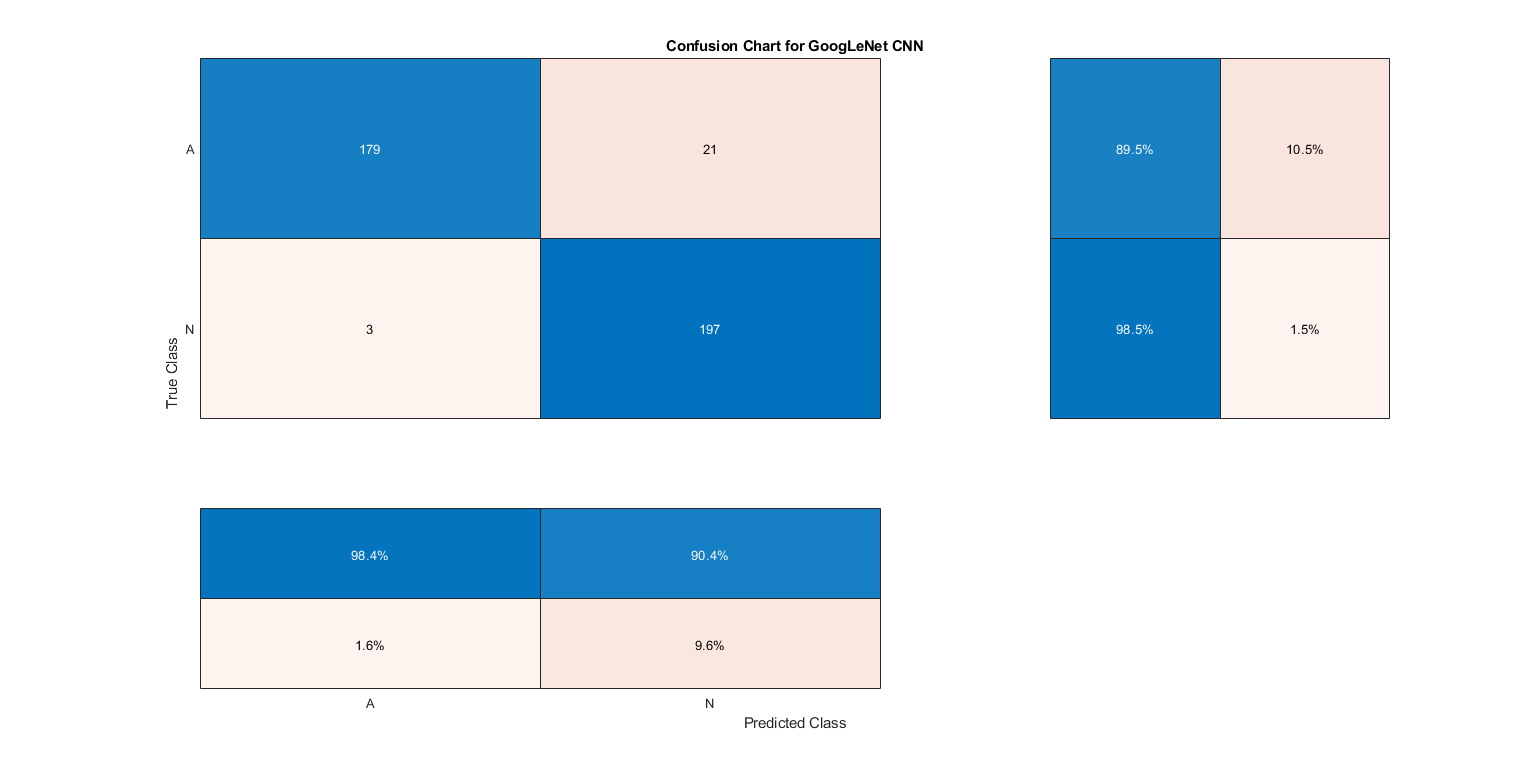

%scores
Predictions = classify(trainedGN,testing);

confusionchart(testing.Labels,Predictions,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for GoogLeNet CNN');

cfsmat = confusionmat(testing.Labels,Predictions);
[acc, p, r, f1] = predictionScores(cfsmat);
disp(['Accuracy: ', num2str(100*acc),'%']);

Accuracy: 94%


disp(['Precision: ', num2str(p)]);

Precision: 0.98352


disp(['Recall: ',num2str(r)]);

Recall: 0.895


disp(['F1 score: ', num2str(f1)]);

F1 score: 0.93717
